clc; clear all; close all;

## Initial data

% NED system. Heading is around Z axis, CCW from above is positive heading. X nose-up is positive pitch, Y
% right down is positive roll
m = 2.;
J = diag([0.01 0.01 0.002]);
tau = 0.2;
Ts = 0.01;
Tf = 5;
tspan = 0:Ts:Tf;
N = Tf / Ts;
l = 250;
ld = 250 * sqrt(2);
Cw = diag([0.01 0.01 0.01]);

## Control coeffs

%% Rate PID gains
Kp_rate = [0.1; 0.1; 0.02];
Ki_rate = [0.00; 0.00; 0.00];
Kd_rate = [0.002; 0.002; 0.001];

%% Attitude PID gains
Kp_att = [0.05; 0.05; 0.02];
Ki_att = [0.00; 0.00; 0.00];
Kd_att = [0.002; 0.002; 0.001];

%% Rate reference limits
rate_ref_lim = deg2rad([100; 100; 80]);   % [p_max; q_max; r_max]

% Parameters
param.J = J;
param.m = m;
param.l = l;
param.ld = ld;
param.rate.Cw = Cw;
% PID Rate
param.rate.Kp = Kp_rate; 
param.rate.Ki = Ki_rate; 
param.rate.Kd = Kd_rate;
% PID attitude
param.att.Kp = Kp_att; 
param.att.Ki = Ki_att; 
param.att.Kd = Kd_att;
param.Ts = Ts; 

## Initial conditions

eul0 = deg2rad([0; 0; 0]);  % [roll, pitch, yaw]
rate0 = deg2rad([0; 2; 0]); % [roll_rate, pitch_rate, yaw_rate]
xIC = [eul0; rate0];

## Simulation

x = xIC;
x_history = zeros(size(xIC, 1), size(tspan,2));
x_history(:, 1) = xIC;
u_history = zeros(3, N+1);
rate_err_hist = zeros(3, N+1);
state_rate.integral = zeros(3,1);
state_rate.prevError = zeros(3,1);

rate_ref = [0;0;0];
eul_ref = [0;0;0];

for k=1:N
    % reference
    ti = tspan(k+1);
    x_true = x_history(:, k);
    rate_err = rate_ref - x(4:6);
    % Rate loop control
    [u, state_rate] = pid_controller(rate_err, state_rate, param.rate.Kp, param.rate.Ki, param.rate.Kd, param.Ts);
    % Simulate dynamic
    xdot_g = @(t, x) copter_dyn(x, u, param);
    [~, xSol] = ode45(xdot_g, [0 Ts], x_true);
    % Store results
    x_history(:, k+1) = xSol(end, :)';
    u_history(:, k) = u;
    rate_err_hist(:, k) = rate_err;
end

## Plot

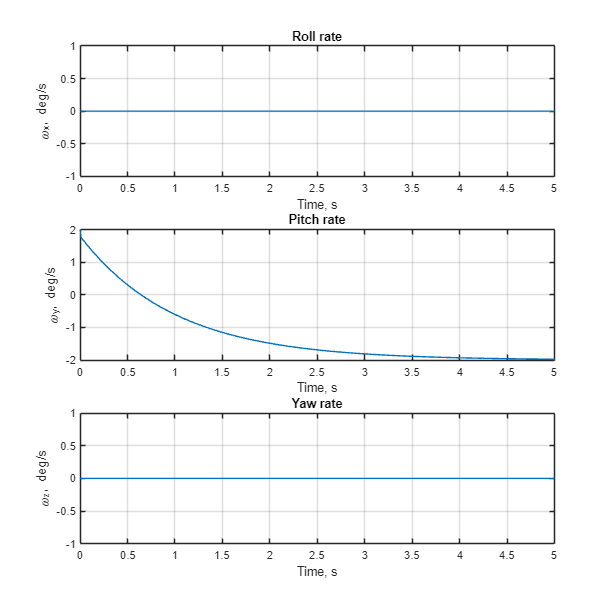

figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(3,1,1);
plot(tspan, rad2deg(x_history(4,:)));
title('Roll rate'); grid; 
xlabel('Time, s'); ylabel('\omega_x, deg/s');

subplot(3,1,2);
plot(tspan, rad2deg(x_history(5,:)));
title('Pitch rate'); grid; 
xlabel('Time, s'); ylabel('\omega_y, deg/s');

subplot(3,1,3);
plot(tspan, rad2deg(x_history(6,:)));
title('Yaw rate'); grid; 
xlabel('Time, s'); ylabel('\omega_z, deg/s');

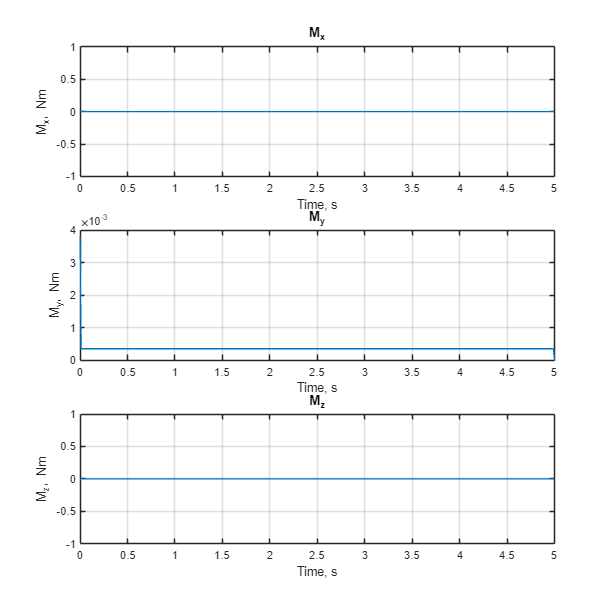

%% Plot control
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(3,1,1); 
plot(tspan, u_history(1,:));
title('M_x'); grid; 
xlabel('Time, s'); ylabel('M_x, Nm');

subplot(3,1,2); 
plot(tspan, u_history(2,:));
title('M_y'); grid; 
xlabel('Time, s'); ylabel('M_y, Nm');

subplot(3,1,3); 
plot(tspan, u_history(3,:));
title('M_z'); grid; 
xlabel('Time, s'); ylabel('M_z, Nm');

## Functions

function rot = E2W(ang)
    % E2W Summary of this function goes here
    % Euler's kinematic for NED
    % Yaw(Z) -> Pitch(Y) -> Roll(Z)
    roll = ang(1);
    pitch = ang(2);
    % yaw = ang(3);
    rot = [
        cos(pitch), sin(roll) * sin(pitch),  cos(roll) * sin(pitch);
        0,          cos(roll) * cos(pitch), -sin(roll) * cos(pitch);
        0,          sin(roll),              cos(roll);
        ]  / cos(pitch);
end

function Nrot = N2B(arg)
    % This is transformation matrix from Launch to Body Frame
    % Yaw(Z)->Pitch(Y)->Roll(X)
    % Unpack the input vector
    phi = arg(1);   % roll
    theta = arg(2); % pitch
    psi = arg(3);   % yaw
    Nrot = rotx(phi) * roty(theta) * rotz(psi);
end


function [u, state] = pid_controller(e, state, Kp, Ki, Kd, Ts)
    % pid_controller - Discrete PID for scalar or vector signals
    %
    % Inputs:
    %   e     - current error (scalar or vector)
    %   state - struct with fields 'integral' and 'prevError'
    %   Kp, Ki, Kd - PID gains (scalar or vector of same size as e)
    %   Ts    - sample time
    %
    % Outputs:
    %   u     - control signal (same size as e)
    %   state - updated state
    
    % Ensure state fields have correct shape
    if isempty(state.integral)
        state.integral = zeros(size(e));
    end
    if isempty(state.prevError)
        state.prevError = zeros(size(e));
    end
    
    % Update integral (elementwise)
    state.integral = state.integral + e .* Ts;
    
    % Derivative (elementwise)
    derivative = (e - state.prevError) ./ Ts;
    
    % PID law (elementwise)
    u = Kp .* e + Ki .* state.integral + Kd .* derivative;
    
    % Update memory
    state.prevError = e;
end


function xnew = copter_dyn(x, u, p)
    eul = x(1:3);
    rate = x(4:6);

    xnew = zeros(6,1);
    xnew(1:3) = E2W(eul) * rate;
    xnew(4:6) = p.J \ (-p.Cw * rate - cross(rate, p.J*rate) + u);
end